# Final Project Part 2, based on *An Introduction to Dynamic Meteorology* Ch. 7.4.2

*By Nicolas Miranda*

### ***Introduction***

This section of Chapter 7.4 from the textbook *An Introduction to Dynamic Meteorology* by Dr. James R. Holton deals with topographic waves: gravity waves which result from flow over rapidly changing topography, such as a mountain range. The equations governing these are actually much simpler than the equations for general, internal gravity waves from Achyutan's section (7.4.1), primarily because topographic waves are always stationary. Mountain ranges do not move (on meteorological timescales), so the vertical perturbations they cause in air orographically forced over them will not move in space either. Topographic waves' crests and troughs thus remain at the same locations in space for a given set of values of average zonal flow, temperature gradients, $N^2$, and all other necessary variables.

In my portion of the project, I wanted to model this wind distribution as a continuation of the study of internal gravity waves. Topographic waves are common in reality and can have some significant effects, such as the formation of lenticular clouds when air parcels are forced upwards, strong heated downslope winds as air parcels are compressed through mountain peaks and forced back downwards, or hazardous turbulence as the topographic waves propagate above the peaks of their generating mountains. Seeing these invisible wind distributions and examining their effects on air parcels (and anything moving through the waves) can help us better understand the hazards of air around mountains.

As mentioned above, the equations for topographic waves are much simpler than those for free-moving internal gravity waves, since topographic waves do not translate over time. The equations from section 7.4.2 of *An Introduction to Dynamic Meteorology* allowed me to calculate winds at any point around my domain analytically. Once I had these wind fields, I was able to code a simple forward euler method to predict the movement of air parcels through said fields. Partial differential equation numerical methods would not have been appropriate, as they would have essentially have been more complicated ways to model the same parcel trajectories (in the absence of diffusion) that the forward euler can more easily do - more on this later.

### *Equations*

The governing equations for topographic waves don't include a time component at all.


$$\left(\frac{\partial^2 w\prime }{\partial x^2 }+\frac{\partial^2 w\prime }{\partial z^2 }\right)+\frac{N^2 }{{\bar{\;u} }^2 }w\prime =0\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\ldotp 46\right)$$
 

is a simplified form of the first equation from Achyutan's section 


$${\left(\frac{\partial }{\partial t}+\bar{u} \frac{\partial }{\partial x}\right)}^2 *\left(\frac{\partial^2 w\prime }{\partial x^2 }+\frac{\partial^2 w\prime }{\partial z^2 }\right)+N^2 \frac{\partial^2 w\prime }{\partial x^2 }=0\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\ldotp 42\right)$$
 

simplified because $w\prime$ now only depends on x and z. Though the textbook is vague on how exactly 7.46 was derived as a simplified form of 7.42, the partial derivative with respect to time completely disappears, since the wind field (based on displacement caused by the underlying topography) is unchanging with respect to time. In 7.46 and 7.42, *w'* represents the vertical velocity perturbation (w itself is assumed to be zero, since air does not rise or sink on average around the globe), $N^2$ is the square of the local atmosphere's buoyancy frequency (calculated based on potential temperature and gravity, $N^2 =g*\frac{d\;\ln \left(\bar{\;\theta \;} \right)}{\mathrm{dz}}$), and $\bar{\;u}$ is the average zonal wind for the domain (avaraged across altitudes and horizontal distances).

7.42 has analytical, harmonic solutions for a waveform - the equation can be solved and split into sine and cosine functions describing the periodic values of vertical velocity over the domain's space. The equation for this is


$$w^{\prime } =\mathrm{Re}\left\lbrack \hat{\;w} *\exp \left(i*\phi \;\right)\right\rbrack =w_r \cos \left(\phi \;\right)-w_i \sin \left(\phi \;\right)\;\;\;\;\;\;\;\;\;\;\;\;\left(7\ldotp 43\right)$$


where $\hat{\;w} =w_r +{i*w}_i$ is the complex amplitude of the wavefunction with real and imaginary parts, and $\phi =k\;x+m\;z-\nu \;t$ is the phase of a gravity wave. 

That last equation is the most important to topographic waves. k is the horizontal wavenumber: the fraction of a wave contained in every unit of the x domain (e.g. 2π/6000 for a wave 6000 units long). m is similar being the vertical wavenumber, though m can also have its own imaginary and real components $m=m_r +i\;m_i$. This might seem unphysical, since a complex wavenumber would mean that there is a complex amount of a wave contained in a unit of vertical depth; however, m being real or complex does produce some fascinating physical effects - again, more on this later.

Rearranging and substituting 7.43 into 7.46 (I am unfortunately unsure of the derivation because the textbook does not detail it) yields a dispersion relationship: an equation for the vertical wavenumber m for topographic waves.


$$m^2 =\frac{N^2 }{{\bar{\;u} }^2 }-k^2 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\ldotp 47\right)$$


k is determined by the mountain range itself, specifically the wavenumber of our idealized sinusoidal mountain range's peaks and valleys. N and ubar are, again, atmospheric parameters.

7.47 does not rule out $m^2$ being negative, and thus m itself being complex. Normally, large N (high atmospheric buyoancy frequency) and small ubar (low average wind speeds) means that the ratio between their squares will be larger than k, and $m^2$ will be positive. However, if N is small, ubar is large, or k is large (high horizontal wavenumber, i.e. less distance between mountain peaks or valleys), $m^2$ can be negative.

Let the height profile of the topography be given by 


$$h\left(x\right)=h_M \cos \left(\mathrm{kx}\right)$$


for a given amplitude (mountaintop height) of the mountain range and a given value of k. This is the idealized, sinusoidal mountain range allowing this approximation to work. Given these heights, the vertical velocity distribution of the topographic waves will be 


$$w\left(x,z\right)=\left\lbrace \begin{array}{ll}
-\bar{\;{u\;h}_M {k\;e}^{-\mu \;z} \sin \left(\mathrm{kx}\right),}  & \bar{\;u} k>N\;\mathrm{equivalently}\;m^2 <0\\
-\bar{\;{u\;h}_M k\sin \left(\mathrm{kx}+\mathrm{mz}\right),}  & \bar{\;\mathrm{uk}} <N\;\mathrm{equivalently}\;m^2 >0
\end{array}\right.\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\ldotp 48\right)$$


for a given combination of x and z coordinates. This equation is found by stating that the airflow around the topography must be parallel to the surface of the mountains. Taking the partial derivative with respect to x of the heights and substituting this into the solution (for w) of 7.46 yields 7.48.

Notice that for real values of m ($m^2 >0$), the oscillation amplitude is unchanged and the phase of a given topographic wave is dependent on its x position *and* z position. This means that for real m, the topographic waves maintain their strength higher in the atmosphere - an odd and likely unphysical occurrence, since turbulence ought to dissipate the energy of topographic waves the farther they are from their generating mountains. For complex m, however, the amplitude diminishes exponentially (given the $e^{-\mu \;z} \;$term multiplying the amplitude, $\mu =|m|$) with altitude, though the phase of a topographic wave becomes dependent only on its x location. This implies that topographic waves, under the conditions where m is complex, diminish in strength as altitude increases.

This is the equation allowing us to calculate the wind field for topographic waves.

An important note before moving on: I am assuming that there is no turbulence affecting the winds of the topographic waves. I am also assuming that there is no acceleration from the Coriolis effect, since the domain of my modeling (200 km zonal x 8 km vertical) is relatively small. Lastly, I am defining the average zonal wind as constant throughout the modeling domain (e.g. vertical winds will vary, but the zonal wind will not).

### *Numerical Methods*

Despite the numerous partial differential equations going into gravity waves and topographic waves, the analytical nature of the winds over topography makes it so that PDEs are not entirely necessary for their modeling. Calculating the winds can be done analytically, given a set of thermodynamic parameters. For tracing an air parcel path through the topographic wave, I implemented the forward euler method


$$\frac{\mathrm{df}}{\mathrm{dt}}=\frac{f\left(t_i +\Delta \;t\right)-f\left(t_i \right)}{\Delta \;t}\Rightarrow f\left(t_i +\Delta \;t\right)=f\left(t_i \right)+\frac{\mathrm{df}}{\mathrm{dt}}\Delta \;t$$


for both the parcel's movement along the x (zonal) axis and the z (vertical) axis. Since the average zonal wind speed is constant, the forward euler method for it became $x\left(t_i +\Delta \;t\right)=x\left(t_i \right)+\bar{\;u} \Delta \;t$. For the vertical wind speed, the forward euler method became $z\left(t_i +\Delta \;t\right)=z\left(t_i \right)+w\left(x\left(t_i \right),z\left(t_i \right)\right)\Delta \;t$.

This was very simple to implement, but I have still been able to see some interesting effects of the wind field from it. I steered away from implementing PDEs because, with diffusion and advection, I realized they would be trying to model the same process of air parcel movement but with unnecessary complexity. The movement of air can be more well-visualized (and more simply visualized) with just streamlines.

### *Code*

%Initialize domain - no time component
xi = 0; %m 
xf = 200*10^3; %m
nx = 200;

Justification for x domain: This is the same x domain that Achyutan used in his section, so I wanted to mirror that in my methods. The parameters will be the same in most cases, until I intentionally vary them later.

zi = 0; %m
zf = 8*10^3; %m
nz = 200;

Justification for z domain: One of the simplifications made in the textbook - that air density can be treated as constant, except for the effects of gravity - is only valid for one scale height of the atmosphere, 8 km (the vertical distance where pressure has decreased, from a reference height, by a factor of $\frac{1}{e}$) .


xs = linspace(xi,xf,nx+1);
zs = linspace(zi,zf,nz+1);

%Choose other constants, based on first part's values
g = 9.8; %m/s^2
t0 = 288; %K
adiabatic_lapse_rate = 9.8; %K/km
avg_temp_gradient = 6.5; %K/km
n2 = g / t0 * abs(adiabatic_lapse_rate - avg_temp_gradient) / 1000; %1/s^2
ubar = 50.0; %m/s

Justification for ubar = 50 m/s: I tried 5 m/s, the value that Achyutan used in his section, and found a result that will need more explanation. For simplicity, I wanted to start with ubar = 50 m/s.


%Wavenumbers
k = 2*pi/(100*10^3);

%Set up blank domain, for quickly properly-sized zeros array
blankDomain = zeros(length(zs),length(xs));

%Set up ground profile, a sinusoidal mountain range
height = 1000;
groundHgts = 100 + height/2 + height/2*cos(k.*(xs-50*10^3)); %100m ground level, plus 1000m tall mountains atop that
groundMask = blankDomain;
for i = 1:length(xs)
    groundMask(:,i) = zs <= groundHgts(i);
end

This height profile differs from what was in the textbook - ironically, to make my figure match the textbook more closely. I will explain this more shortly.

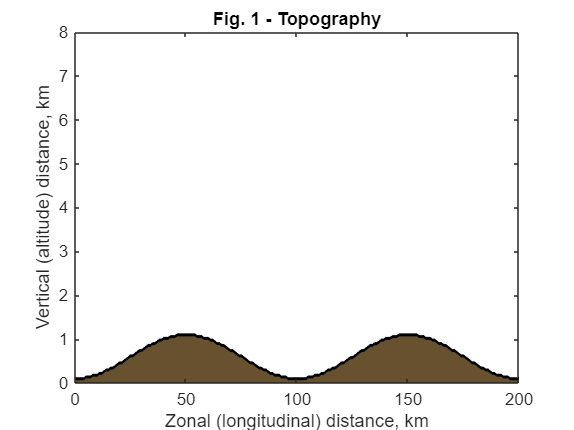


%Plot mountain range, for visual reference
figure(1)
clf

groundCmap = [1,1,1;105/256,82/256,48/256];
[xx,zz] = meshgrid(xs,zs);
contourf(xx./1000,zz./1000,groundMask);
colormap(groundCmap);
title('Fig. 1 - Topography')
xlabel('Zonal (longitudinal) distance, km')
ylabel('Vertical (altitude) distance, km')

Fig. 1 shows the idealized sinusoidal topography.


%Finding vertical wind structures
function wOut = verticalWinds(n,ubar,k,height,x,z)
    m = sqrt(n^2/(ubar^2)-k^2);
    
    wOut = 0;
    if (m^2 > 0)
        wOut = -ubar.*height/2.*k.*sin(k*(x-50*10^3)+m*z);
    elseif (m^2 < 0)
        wOut = -ubar.*height/2.*k.*exp(-abs(m)*z).*sin(k*(x-50*10^3));
    end
end

This formula for the vertical wind field differs from what is in the textbook (7.48). Since my height profile was different than that of the textbook, I derived a new vertical wind calculation based on the same process the textbook used: taking the partial derivative, with respect to x, of the height profile.

From the textbook:

$w\prime \left(x,0\right)=\bar{\;u} \frac{\partial h}{\partial x}$,

so for my derivation,


$$w^{\prime } \left(x,0\right)=\bar{\;u} \frac{\partial h}{\partial x}=\bar{\;u} \frac{\partial }{\partial x}\left(100+\frac{h_m }{2}+\frac{h_m }{2}\cos \left(k*\left(x-50*{10}^3 \right)\right)\right)=\bar{\;-u*\frac{h_m }{2}*k*\sin \left(k*\left(x-50*{10}^3 \right)\right)}$$
 

I then plugged this into the wind field calculation to get my version,


$$w\left(x,z\right)=\left\lbrace \begin{array}{ll}
-\bar{\;\frac{{u\;h}_M }{2}{k\;e}^{-\mu \;z} \sin \left(k\left(x-50*{10}^3 \right)\right),}  & \bar{\;u} k>N\;\mathrm{equivalently}\;m^2 <0\\
-\bar{\;\frac{{u\;h}_M }{2}k\sin \left(k\left(x-50*{10}^3 \right)+\mathrm{mz}\right),}  & \bar{\;\mathrm{uk}} <N\;\mathrm{equivalently}\;m^2 >0
\end{array}\right.$$


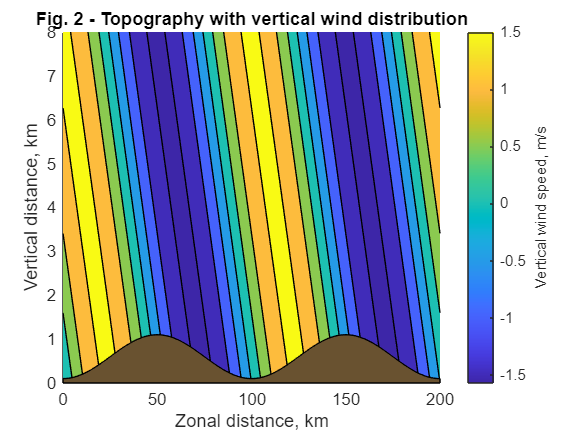


for x = 1:length(xs)
    for z = 1:length(zs)
        wMat(z,x) = verticalWinds(sqrt(n2),ubar,k,height,xs(x),zs(z));
    end
end

figure(2)
clf
hold on

contourf(xx./1000,zz./1000,wMat,'FaceAlpha',1)
fill([xs./1000 fliplr(xs./1000)], [zeros(1,length(xs)) fliplr(groundHgts./1000)], ...
    groundCmap(2,:))
%Above line, showing topography overlay, aided by ChatGPT

title('Fig. 2 - Topography with vertical wind distribution')
xlabel('Zonal distance, km')
ylabel('Vertical distance, km')
c2 = colorbar;
c2.Label.String = 'Vertical wind speed, m/s';

hold off

The filled contours show vertical velocity, while topography remains visible at the bottom of the graph.

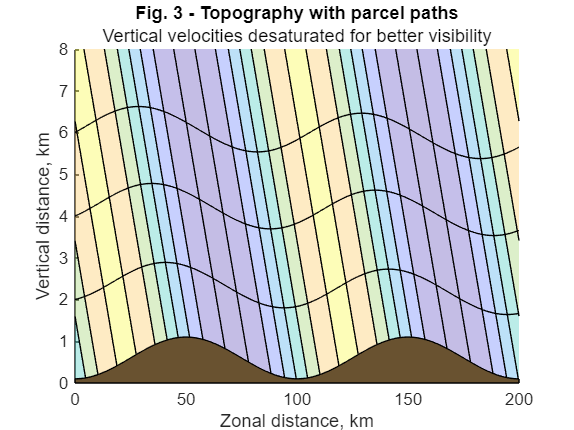


%Trace streamlines through the vertical wind distribution
%March forward in space with forward euler
function path = forwardEuler(n,ubar,k,height,xs,zStart,tStep)
    %Calculate time steps
    pathTime = max(xs)/ubar;
    ts = 1:tStep:pathTime;

    path = zeros(length(ts),2); %First col x, second col z
    path(1,2) = zStart;

    %Begin for. euler loop
    for t = 2:length(ts)
        path(t,1) = path(t-1,1) + ubar*tStep; %Calculating next x location
        path(t,2) = path(t-1,2) + verticalWinds(n,ubar,k,height, ...
            path(t-1,1),path(t-1,2))*tStep;
    end
end

path1 = forwardEuler(sqrt(n2),ubar,k,height,xs,2000,0.1);
path2 = forwardEuler(sqrt(n2),ubar,k,height,xs,4000,0.1);
path3 = forwardEuler(sqrt(n2),ubar,k,height,xs,6000,0.1);

%Plot parcel paths
figure(3)
clf
hold on

contourf(xx./1000,zz./1000,wMat,'FaceAlpha',0.3)
fill([xs./1000 fliplr(xs./1000)], [zeros(1,length(xs)) fliplr(groundHgts./1000)], ...
    groundCmap(2,:))

plot(path1(:,1)./1000,path1(:,2)./1000,'k')
plot(path2(:,1)./1000,path2(:,2)./1000,'k')
plot(path3(:,1)./1000,path3(:,2)./1000,'k')

title('Fig. 3 - Topography with parcel paths')
subtitle('Vertical velocities desaturated for better visibility')
xlabel('Zonal distance, km')
ylabel('Vertical distance, km')

hold off

Finally, parcel paths show how an air parcel reacts to the velocity changes over the mountaintops.

### *Results*

Figure 2 shows the vertical velocity distribution clearly. There is clearly a periodic form to the vertical velocity, and as the idealized equations suggest, the strength of vertical velocity changes (the amplitude of the oscillation) does not diminish with height since m is real. This stil seems unrealistic, since turbulence ought to sap away at the kinetic energy of the vertical winds until they return to the background state (zero). That said, this is an idealized simulation. Figure 3 shows that parcel paths follow the vertical velocity changes in an expected, sinusoidal way, though there is a slight loss of elevation from the western side of the domain to the eastern.

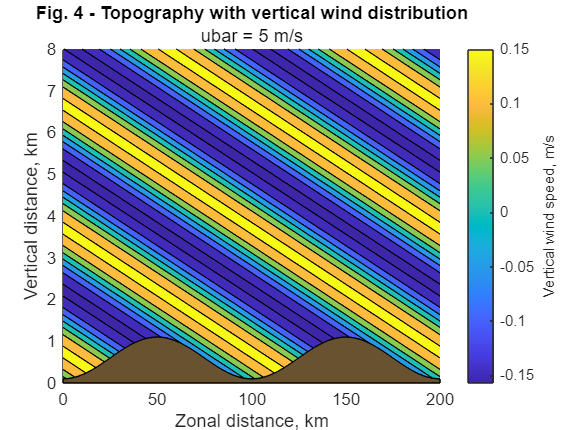

ubar = 5.0; %m/s

for x = 1:length(xs)
    for z = 1:length(zs)
        wMat(z,x) = verticalWinds(sqrt(n2),ubar,k,height,xs(x),zs(z));
    end
end

figure(2)
clf
hold on

contourf(xx./1000,zz./1000,wMat,'FaceAlpha',1)
fill([xs./1000 fliplr(xs./1000)], [zeros(1,length(xs)) fliplr(groundHgts./1000)], ...
    groundCmap(2,:))
%Above line, showing topography overlay, aided by ChatGPT

title('Fig. 4 - Topography with vertical wind distribution')
subtitle('ubar = 5 m/s')
xlabel('Zonal distance, km')
ylabel('Vertical distance, km')
c2 = colorbar;
c2.Label.String = 'Vertical wind speed, m/s';

hold off

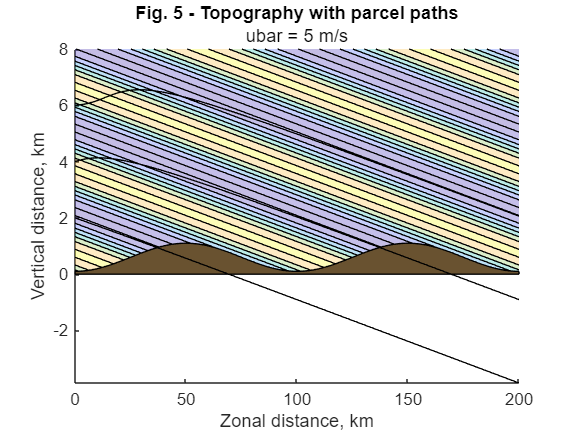


path1 = forwardEuler(sqrt(n2),ubar,k,height,xs,2000,0.1);
path2 = forwardEuler(sqrt(n2),ubar,k,height,xs,4000,0.1);
path3 = forwardEuler(sqrt(n2),ubar,k,height,xs,6000,0.1);

%Plot parcel paths
figure(3)
clf
hold on

contourf(xx./1000,zz./1000,wMat,'FaceAlpha',0.3)
fill([xs./1000 fliplr(xs./1000)], [zeros(1,length(xs)) fliplr(groundHgts./1000)], ...
    groundCmap(2,:))

plot(path1(:,1)./1000,path1(:,2)./1000,'k')
plot(path2(:,1)./1000,path2(:,2)./1000,'k')
plot(path3(:,1)./1000,path3(:,2)./1000,'k')

title('Fig. 5 - Topography with parcel paths')
subtitle('ubar = 5 m/s')
xlabel('Zonal distance, km')
ylabel('Vertical distance, km')

hold off

Modifying ubar to 5 m/s shows some interesting results. m remains real, so the vertical velocity field does not diminish at altitude (as shown in Fig. 4), but the in Fig. 5 the parcel paths dive straight into the mountains, unable to progress beyond the regions of negative vertical velocity. I believe that this unintentionally models cold air damming; if ubar (the average zonal velocity) is too low, the wind does not have enough kinetic energy, even in this idealized situation, to force itself over the topography and be able to oscillate. It gets stuck in a downward-forced area and must find another way around the mountain range. This effect can lead to the "wedge" in northeastern Georgia, advecting cold air from the north Atlantic along the Appalachians and causing cloudy skies in the southeastern U.S.

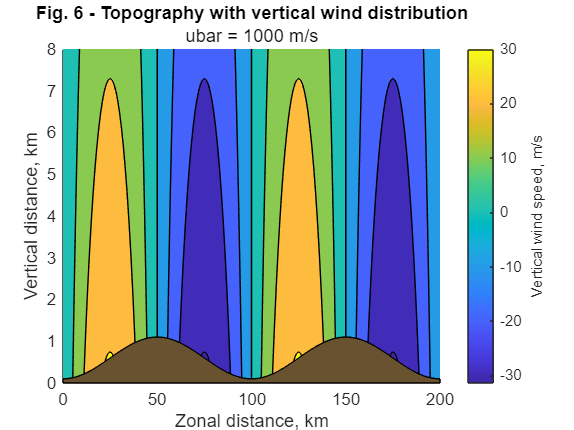

ubar = 1000.0; %m/s

for x = 1:length(xs)
    for z = 1:length(zs)
        wMat(z,x) = verticalWinds(sqrt(n2),ubar,k,height,xs(x),zs(z));
    end
end

figure(2)
clf
hold on

contourf(xx./1000,zz./1000,wMat,'FaceAlpha',1)
fill([xs./1000 fliplr(xs./1000)], [zeros(1,length(xs)) fliplr(groundHgts./1000)], ...
    groundCmap(2,:))
%Above line, showing topography overlay, aided by ChatGPT

title('Fig. 6 - Topography with vertical wind distribution')
subtitle('ubar = 1000 m/s')
xlabel('Zonal distance, km')
ylabel('Vertical distance, km')
c2 = colorbar;
c2.Label.String = 'Vertical wind speed, m/s';

hold off

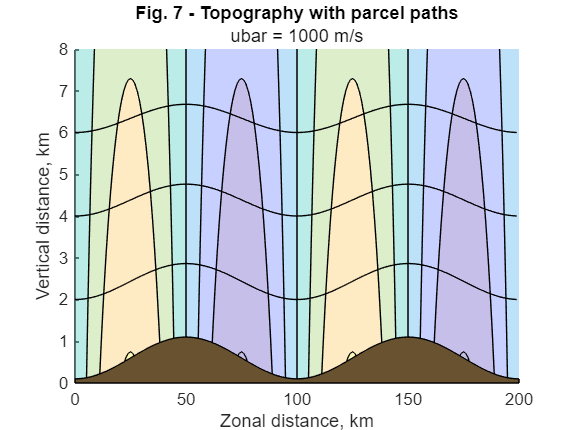


path1 = forwardEuler(sqrt(n2),ubar,k,height,xs,2000,0.1);
path2 = forwardEuler(sqrt(n2),ubar,k,height,xs,4000,0.1);
path3 = forwardEuler(sqrt(n2),ubar,k,height,xs,6000,0.1);

%Plot parcel paths
figure(3)
clf
hold on

contourf(xx./1000,zz./1000,wMat,'FaceAlpha',0.3)
fill([xs./1000 fliplr(xs./1000)], [zeros(1,length(xs)) fliplr(groundHgts./1000)], ...
    groundCmap(2,:))

plot(path1(:,1)./1000,path1(:,2)./1000,'k')
plot(path2(:,1)./1000,path2(:,2)./1000,'k')
plot(path3(:,1)./1000,path3(:,2)./1000,'k')

title('Fig. 7 - Topography with parcel paths')
subtitle('ubar = 1000 m/s')
xlabel('Zonal distance, km')
ylabel('Vertical distance, km')

hold off

Lastly, if the winds increase to 1000 m/s (typical of wind speeds on the gas giant planets), we see the other side of the vertical wind speed calculation: when m is complex. Fig. 6 shows that the structure of vertical velocity oscillations is completely different: they diminish exponentially with height, with the strongest positive and negative values of velocity being near the surface. It is hard to see, but the parcel path oscillations in Fig. 7 also decrease in amplitude as altitude increases. The textbook implies that this diminishment of amplitude should be more pronounced and the exponential fall-off strong, so I do not know why my code is showing a more subtle decrease. However, all of my results agree with the textbook's examples. I think that this case is the most realistic, since the amplitude of parcel oscillations smooths out as they get farther away from the forcing mechanism: the topography.

### *References*

Holton, J. R., 2004: Atmospheric Oscillations: Linear Perturbation Theory. *An Introduction to Dynamic Meteorology, *J. R. Holton, Ed, Elsevier Inc., 201-204.